## Matlab code for generateing main figure 5 in the following paper:

[Single cell transcriptomics of human epidermis identifies basal stem cell transition states](https://www.nature.com/articles/s41467-020-18075-7), S. Wang, M. Drummond, C.Guerrero-Juarez, E.Tarapore, A.MacLean, A. Stabell, S. Wu, G. Gutierrez, B. That, C. Benavente, Q. Nie & S. X. Atwood, Nature Communications, 2020.

- All the results are generated by applying SoptSC to the single-cell rna-seq data, for detailed useage of SoptSC, please refer to

- [https://github.com/WangShuxiong/SoptSC](https://github.com/WangShuxiong/SoptSC)

- Some figures are generated using custermized code below

% Add tools into matlab path
addpath('Data');
addpath('NNDSVD');
addpath('symnmf2');
addpath('EE');
addpath('vinlinplot');
addpath('scTools');
addpath('scTools/graphViz2Mat1');
addpath('Cell_Cell_Communication');
addpath('gephi');
addpath('Results');

#### Step 1 (Required)

Load data

%% Step 1: load data
load Data/Data_Figure5.mat;

% set folder to save all figures
folder = 'Results\Fig5';
folder1 = 'Results/Fig5';

%% Fig5A
figname = 'Fig5A';
method = 'GRAPH';
cluster_order = 1:Data_Figure5.No_cluster; % cluster orders for plots
plot_cluster(Data_Figure5.latent,Data_Figure5.cluster_label,Data_Figure5.No_cluster,Data_Figure5.cluster_legend,folder,...
    cluster_order,method,figname,Data_Figure5.cluster_color);

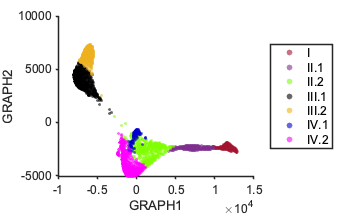

%% Fig5B
figname = 'Fig5B';

topn = 10;
GC_htmp_DE_lgd(Data_Figure5.data,Data_Figure5.allgenes,Data_Figure5.cluster_label,topn,Data_Figure5.cluster_legend,figname,...
    folder,folder1);

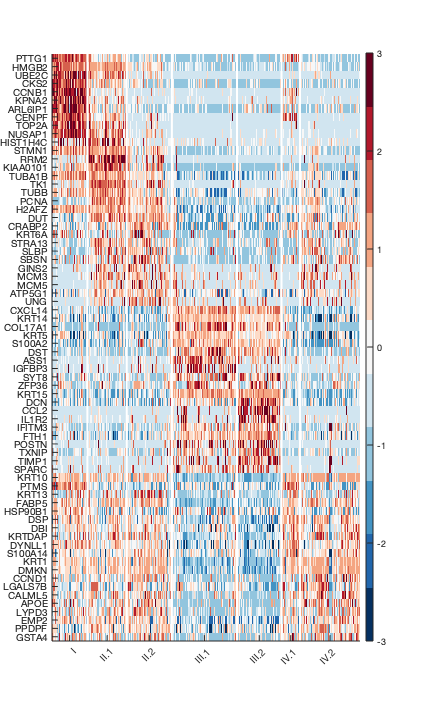

%% Fig5D
method = 'GRAPH';
figname = 'Fig5D';

plot_pseudotime(Data_Figure5.latent,Data_Figure5.pseudotime,folder,figname,method);

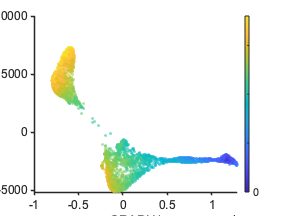

%% Fig5F
figname = 'Fig5F';
Marker = {'KRT14';'KRT10'};


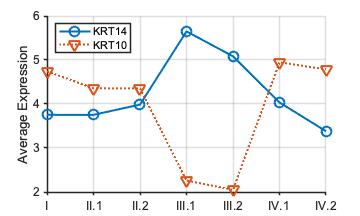

%
[~,~,Mk_idx] = intersect(Marker,Data_Figure5.allgenes,'stable');
data_mk = Data_Figure5.data(Mk_idx,:);
Mk_in_list = Data_Figure5.allgenes(Mk_idx);

data_mk1_mean = data_mk(1,:);
data_mk2_mean = data_mk(2,:);

%% average with each cluster
for i = 1:Data_Figure5.No_cluster
    data_mk1_mean_C(i) = mean(data_mk1_mean(Data_Figure5.cluster_label==i));
    data_mk2_mean_C(i) = mean(data_mk2_mean(Data_Figure5.cluster_label==i));
end

order = 1:Data_Figure5.No_cluster;
plot_KRT1014(Data_Figure5.cluster_legend,Marker,order,data_mk1_mean_C,data_mk2_mean_C,folder,figname);